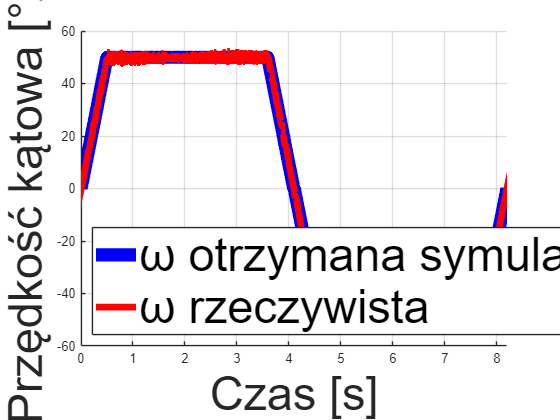

clc; clear;

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(50);   
a_max = deg2rad(100);  
dt = 0.01;

q_home = [-0, -90, 0, -90, 0.000, -0.000]*pi/180;
q_end  = [180, -90, 0, -90, 0.000, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;
    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);  

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);
[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];


M = csvread('6212_ums.csv', 1,0);
idxB = 1; idxE = length(M);
M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-5.17), SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.2]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 517;                        
omega_ref = qd_traj(:,1) * 180/pi;    
omega_meas = SDLData.gZ;              
omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);
omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));
fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 0.677840 [°/s]



I_omega_t = abs(omega_ref - omega_meas_shifted);
time_vec = T_full(1:N);   

figure;
subplot(1,2,1)
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 8.18]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(1,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

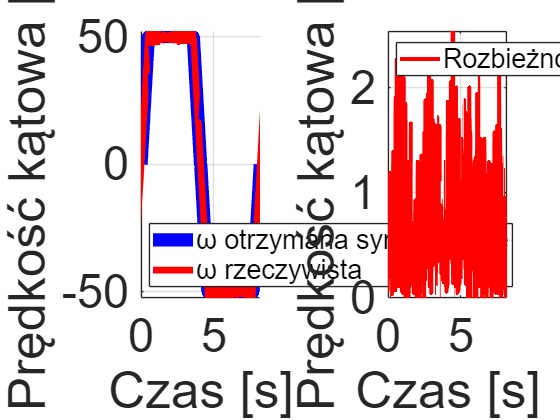

set(gca, 'FontSize', 35)
xlim([0 8.18]);

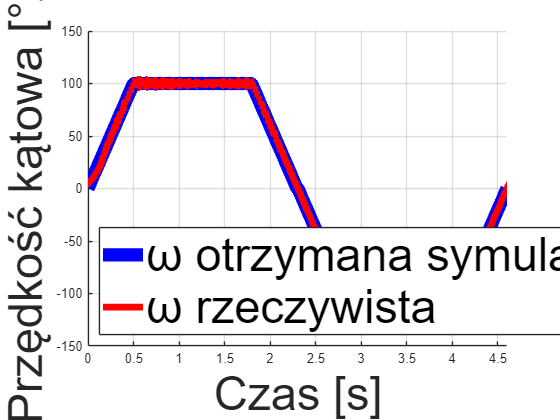

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(100);
a_max = deg2rad(200);
dt = 0.01;

q_home = [-0, -90, 0, -90, 0.000, -0.000]*pi/180;
q_end  = [180, -90, 0, -90, 0.000, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);
[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];


M = csvread('6221_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-1.71), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.6]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 171;
omega_ref = qd_traj(:,1) * 180/pi;
omega_meas = SDLData.gY;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));
fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 1.621696 [°/s]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T_full(1:N);

figure;
subplot(1,2,1)
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.58]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(1,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

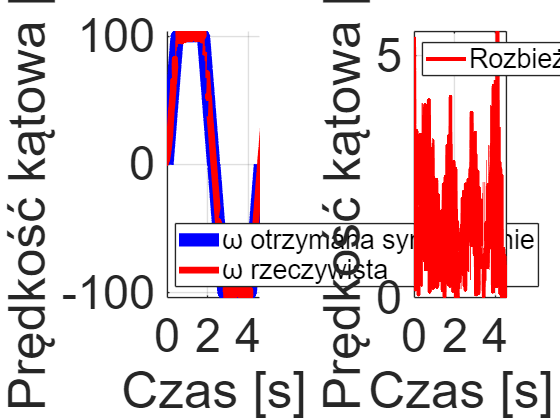

set(gca, 'FontSize', 35)
xlim([0 4.58]);

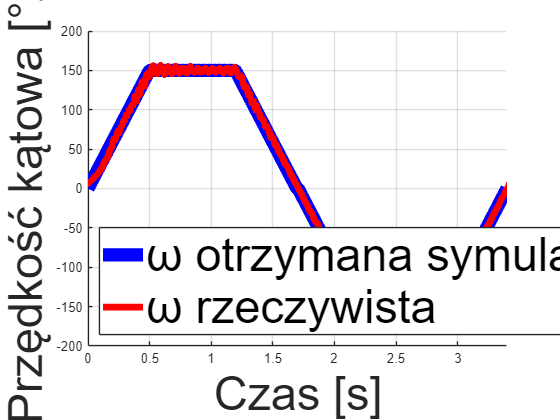

ur3 = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0 0 -9.81]);

v_max = deg2rad(150);
a_max = deg2rad(300);
dt = 0.01;

q_home = [-0, -90, 0, -90, 0.000, -0.000]*pi/180;
q_end  = [180, -90, 0, -90, 0.000, -0.000]*pi/180;

q_home = q_home(:); 
q_end = q_end(:);   

dq = abs(q_end - q_home);
t_total_joint = zeros(6,1);

for i = 1:6
    if dq(i) < 1e-4
        t_total_joint(i) = 0.5;
        continue;
    end
    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if dq(i) < 2*d_acc
        t_total_joint(i) = 2 * sqrt(dq(i) / a_max);
    else
        t_total_joint(i) = 2*t_acc + (dq(i) - 2*d_acc)/v_max;
    end
end

trajTime = max(t_total_joint);

nSteps = ceil(trajTime / dt);
T_vec = linspace(0, trajTime, nSteps);
[qt1, qd1, qdd1] = trapveltraj([q_home, q_end], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

[qt2, qd2, qdd2] = trapveltraj([q_end, q_home], nSteps, 'AccelTime', v_max/a_max, 'EndTime', trajTime);

q_traj = [qt1'; qt2'];
qd_traj = [qd1'; qd2'];
qdd_traj = [qdd1'; qdd2'];
T_full = linspace(0, 2*trajTime, 2*nSteps);

TCP_pos = zeros(2*nSteps, 6);
for i = 1:2*nSteps
    T = getTransform(ur3, q_traj(i,:), 'tool0');
    TCP_pos(i,1:3) = tform2trvec(T);
    TCP_pos(i,4:6) = tform2eul(T);
end

TCP_vel = [zeros(1,6); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,6); diff(TCP_vel)/dt];



M = csvread('6231_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-1.86), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.4]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 186;
omega_ref = qd_traj(:,1) * 180/pi;
omega_meas = SDLData.gY;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 2.393387 [°/s]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T_full(1:N);

figure;
subplot(1,2,1)
hold on;
plot(T_full, qd_traj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-offset/100), SDLData.gY, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.38]); 
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(1,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

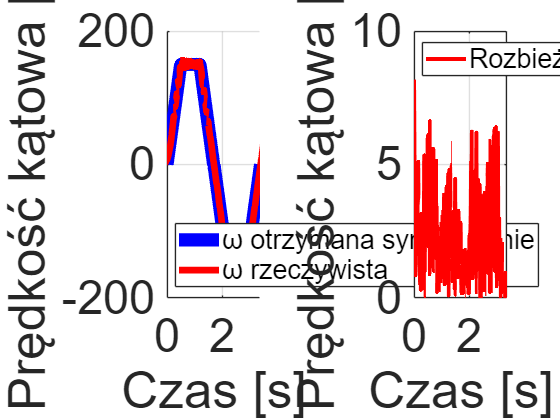

set(gca, 'FontSize', 35)
xlim([0 3.38]);